# Physics Based Dynamic Modeling

Dynamic models are essential for understanding the system dynamics in open-loop (manual mode) or for closed-loop (automatic) control. These models are either derived from data (empirical) or from more fundamental relationships (first principles, physics-based) that rely on knowledge of the process. A combination of the two approaches is often used in practice where the form of the equations are developed from fundamental balance equations and unknown or uncertain parameters are adjusted to fit process data.

In engineering, there are 4 common balance equations from conservation principles including mass, momentum, energy, and species . An alternative to physics-based models is to use input-output data to develop empirical dynamic models such as first-order or second-order systems.

## Steps in Dynamic Modeling

The following are general guidelines for developing a dynamic model. The process is iterative as simulation results help inform modeling assumptions or correct errors in the dynamic balance equations.

- Identify objective for the simulation

- Draw a schematic diagram, labeling process variables

- List all assumptions

- Determine spatial dependence

- Write dynamic balances (mass, species, energy)

- Other relations (thermo, reactions, geometry, etc.)

- Degrees of freedom, does number of equations = number of unknowns?

- Classify inputs as: FC, Disturbance, MV

- Classify outputs as: States, Controlled Variable

- Simplify balance equations based on assumptions

- Simulate steady state conditions (if possible)

- Simulate the output with an input step

### Example: Filling a Water Tank

Consider a cylindrical tank with no outlet flow and an adjustable inlet flow. The inlet flow rate is not measured but there is a level measurement that shows how much fluid has been added to the tank. The objective of this exercise is to develop a model that can maintain a certain water level by automatically adjusting the inlet flow rate.

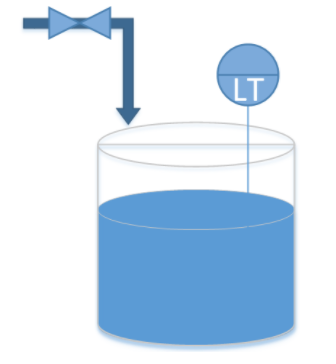

Above is a diagram of a tank with an inlet and no outlet. The symbol **LT** is an abbreviation for *Level Transmitter.*

### **Balance equation:**

A first step is to develop a dynamic model of how the inlet flow rate affects the level in the tank. A starting point for this model is a balance equation.


$$\frac{dm}{dt} = \dot{m}_{in} -  \dot{m}_{out} $$


The accumulation term is a differential variable such as *dm/dt* for mass. In this case, the accumulation of mass is equal to only an inlet flow and no outlet, generation, or consumption terms.

**Assumptions**

The next objective is to simplify the expression and transform it into a relationship between height $h$ and the valve opening $u$* (0-100%)*. For liquid water, density is nearly constant even over wide temperature ranges and the mass is equal to the density multiplied by the volume $V$. Assuming a constant cross-sectional area gives $V =hA$ and a linear correlation between valve opening and inlet flow gives the following relationship.

$\rho A \frac{dh}{dt}=cu$ where $\dot{m}_{in} =cu$

where $c$ is a constant that relates valve opening to inlet flow

**Problem**

Simulate the height of a tank by integrating the mass balance equation for a period of 10 seconds. The valve opens to 100% at time=2 and shuts at time=7. Use a value of $1000 \frac {\text{kg}}{\text{m}^3}$ for density and $1.0\ \text{m}^2$ for the cross-sectional area of the tank. For the valve, assume a valve coefficient of $\text{c}=50.0 \frac{\text{kg/s}}{\text{\% open}}$.

% INSERT PROBLEM SOLUTION BELOW
%%%%%%%%%%%%%%%%%%%%








### Solution

[insert Solution Video Here]